## 数据导入-山西省

filename = 'D:\Drivers\CarbonEmissiondata\Shanxi_data.xlsx'; 
dataTable = readtable(filename);

dataGDP_ren = dataTable.Per_capita_GDP_yuan(1:25);
dataGDP = dataGDP_ren.';

dataPopulation_wan = dataTable.Population_wan(1:25);
dataPopulation = dataPopulation_wan.';
disp(dataPopulation)

   1.0e+03 *

    3.1770    3.2005    3.2240    3.2470    3.2720    3.2940    3.3140    3.3350    3.3550    3.3750    3.3930    3.4110    3.4270    3.5740    3.5620    3.5480    3.5350    3.5280    3.5190    3.5140    3.5100    3.5020    3.4970    3.4900    3.4800



dataSecond_billion = dataTable.Value_added_of_the_secondary_industry_billion(1:25);
dataSecond = dataSecond_billion.';

dataCE_mt = dataTable.CarbonEmissions_mt(1:25);
%dataCE = dataCE_mt.';

dataCoal_tons = dataTable.Coal_consumption_10000_tons(1:25);
dataCoke_tons = dataTable.Coke_consumption_10000_tons(1:25);
dataFuel_tons = dataTable.Fuel_oil_consumption_10000_tons(1:25);
energyconsumption= (dataCoal_tons+dataCoke_tons+dataFuel_tons);
dataEnergy = energyconsumption.';
disp(dataEnergy)

   1.0e+04 *

    1.5987    1.6527    1.4988    1.5546    1.7026    2.0817    2.3587    2.5157    2.7821    3.0768    3.1730    3.0731    3.0200    3.2454    3.6038    3.7490    3.8782    3.9765    3.9199    3.7819    4.4901    5.1326    5.3858    5.8985    6.3464




dataNatural_meters = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25);
dataNaturalgas = dataNatural_meters.';

dataTechnology_million = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25);
dataTechnology = dataTechnology_million.';

%dataFirepower_kilowatt= dataTable.Thermal_power_generation_100_million_kilowatt_hours(1:26);
%dataFire = dataFirepower_kilowatt.';

dataWaterpower_kilowatt= dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25);
%dataWater = dataWaterpower_kilowatt.';

dataTotalpower_kilowatt= dataTable.Total_power_generation_100_million_kilowatt_hours(1:25);
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_2=(dataWaterpower_kilowatt/dataTotalpower_kilowatt);
%dataWaterpercent=dataWaterpercent_2.';


## 人均GDP的LSTM模型

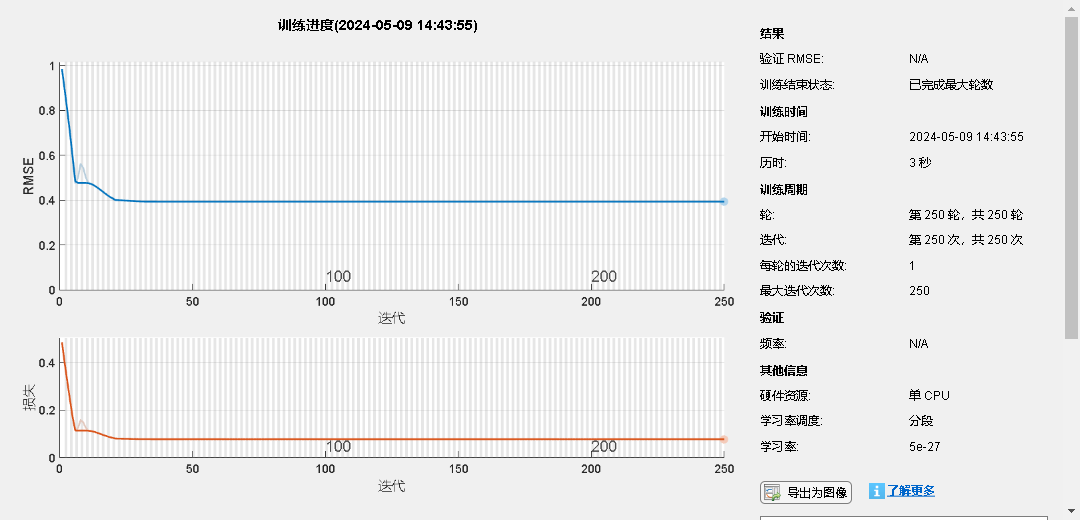

numTimeStepsTrain = numel(dataGDP); 
dataTrainGDP = dataGDP(1 : numTimeStepsTrain);
% 数据标准化，零均值和单位方差
muGDP = mean(dataTrainGDP);
sigGDP = std(dataTrainGDP);
dataTrainStandardizedGDP = (dataTrainGDP - muGDP) / sigGDP;
% 训练数据
XTrainGDP = dataTrainStandardizedGDP(1:end-1);
YTrainGDP = dataTrainStandardizedGDP(2:end);
% 创建 LSTM 网络
numFeaturesGDP = 1;
numResponsesGDP = 1;
numHiddenUnitsGDP = 50;

layersGDP = [sequenceInputLayer(numFeaturesGDP)
          lstmLayer(numHiddenUnitsGDP)
          fullyConnectedLayer(numResponsesGDP)
          regressionLayer];

% 设置网络参数
optionsGDP = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netGDP = trainNetwork(XTrainGDP, YTrainGDP, layersGDP, optionsGDP);

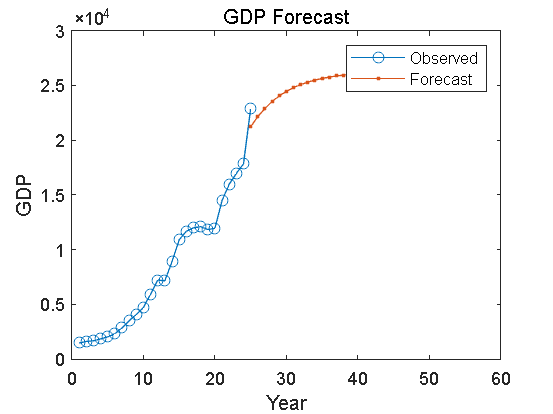

% 预测
netGDP = predictAndUpdateState(netGDP, XTrainGDP);
% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netGDP, YPredGDP] = predictAndUpdateState(netGDP, YTrainGDP(end));

% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictGDP = 28;
YPredGDP = [YPredGDP zeros(1, numYearsToPredictGDP - 1)]; % 预分配预测数组
for i = 2:numYearsToPredictGDP
    [netGDP, YPredGDP(:, i)] = predictAndUpdateState(netGDP, YPredGDP(:, i-1), 'ExecutionEnvironment', 'cpu');
end
% 去标准化
YPredGDP = sigGDP * YPredGDP + muGDP;
% 画图
figure;
plot(1:numel(dataGDP), dataGDP, '-o')
hold on
idx = numel(dataGDP) : (numel(dataGDP) + numYearsToPredictGDP - 1);
plot(idx, YPredGDP, '.-')
hold off 
xlabel("Year");
ylabel("GDP");
title("GDP Forecast");
legend("Observed", "Forecast");

%writematrix(YPred, 'D:\Drivers\LSTM_liaoningCEdata.xlsx'); % 修改为实际文件路径
disp(YPredGDP)

   1.0e+04 *

    2.1223    2.2137    2.2893    2.3520    2.4035    2.4453    2.4794    2.5070    2.5295    2.5479    2.5629    2.5752    2.5854    2.5939    2.6009    2.6067    2.6116    2.6158    2.6193    2.6222    2.6247    2.6269    2.6287    2.6303    2.6316    2.6328    2.6338    2.6346



## 人口的LSTM模型

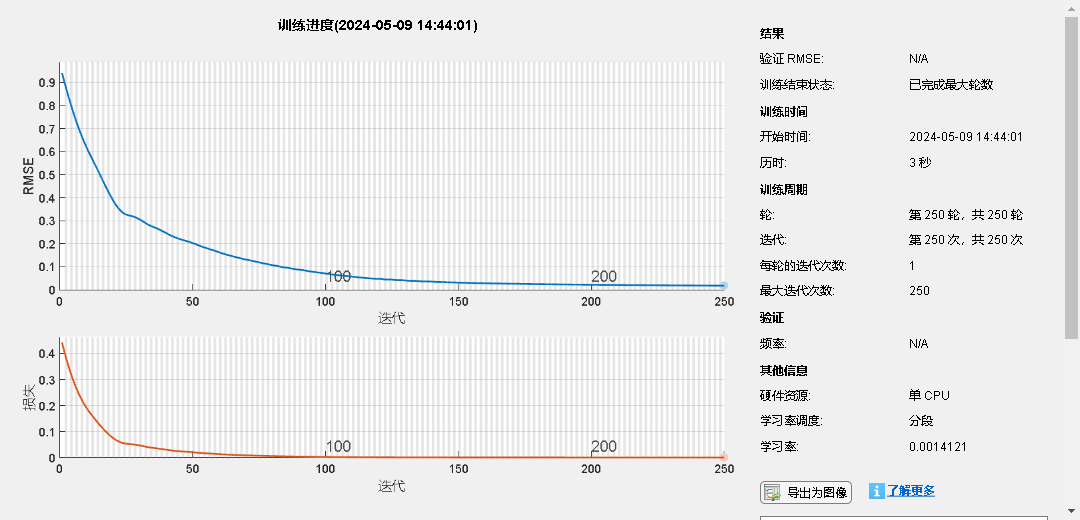

numTimeStepsTrainPopulation = numel(dataPopulation); 
dataTrainPopulation = dataPopulation(1 : numTimeStepsTrainPopulation);

% 数据标准化，零均值和单位方差
muPopulation = mean(dataTrainPopulation);
sigPopulation = std(dataTrainPopulation);
dataTrainStandardizedPopulation = (dataTrainPopulation - muPopulation) / sigPopulation;

% 训练数据
XTrainPopulation = dataTrainStandardizedPopulation(1:end-1);
YTrainPopulation = dataTrainStandardizedPopulation(2:end);

% 创建 LSTM 网络
numFeaturesPopulation = 1;
numResponsesPopulation = 1;
numHiddenUnitsPopulation = 20;

layersPopulation = [sequenceInputLayer(numFeaturesPopulation)
          lstmLayer(numHiddenUnitsPopulation)
          fullyConnectedLayer(numResponsesPopulation)
          regressionLayer];

% 设置网络参数
optionsPopulation = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.9, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netPopulation = trainNetwork(XTrainPopulation, YTrainPopulation, layersPopulation, optionsPopulation);

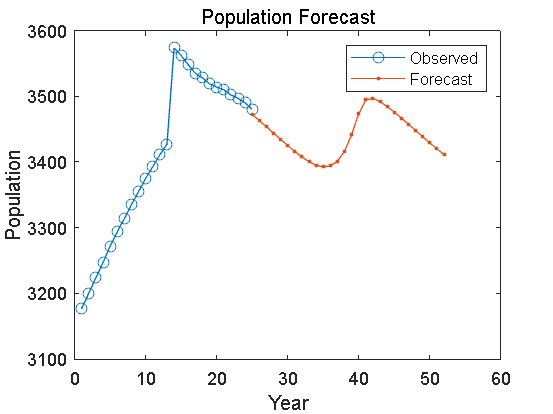


% 预测
netPopulation = predictAndUpdateState(netPopulation, XTrainPopulation);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netPopulation, YPredPopulation] = predictAndUpdateState(netPopulation, YTrainPopulation(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictPopulation = 28;
YPredPopulation = [YPredPopulation zeros(1, numYearsToPredictPopulation - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictPopulation
    [netPopulation, YPredPopulation(:, i)] = predictAndUpdateState(netPopulation, YPredPopulation(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredPopulation = sigPopulation * YPredPopulation + muPopulation;
% 画图
figure;
plot(1:numel(dataPopulation), dataPopulation, '-o')
hold on
idx = numel(dataPopulation) : (numel(dataPopulation) + numYearsToPredictPopulation - 1);
plot(idx, YPredPopulation, '.-')
hold off 
xlabel("Year");
ylabel("Population");
title("Population Forecast");
legend("Observed", "Forecast");

disp(YPredPopulation)

   1.0e+03 *

    3.4723    3.4631    3.4537    3.4441    3.4344    3.4250    3.4160    3.4077    3.4005    3.3951    3.3925    3.3940    3.4012    3.4164    3.4417    3.4735    3.4946    3.4968    3.4916    3.4843    3.4759    3.4669    3.4575    3.4480    3.4384    3.4290    3.4199    3.4114



## 第二产业的LSTM模型

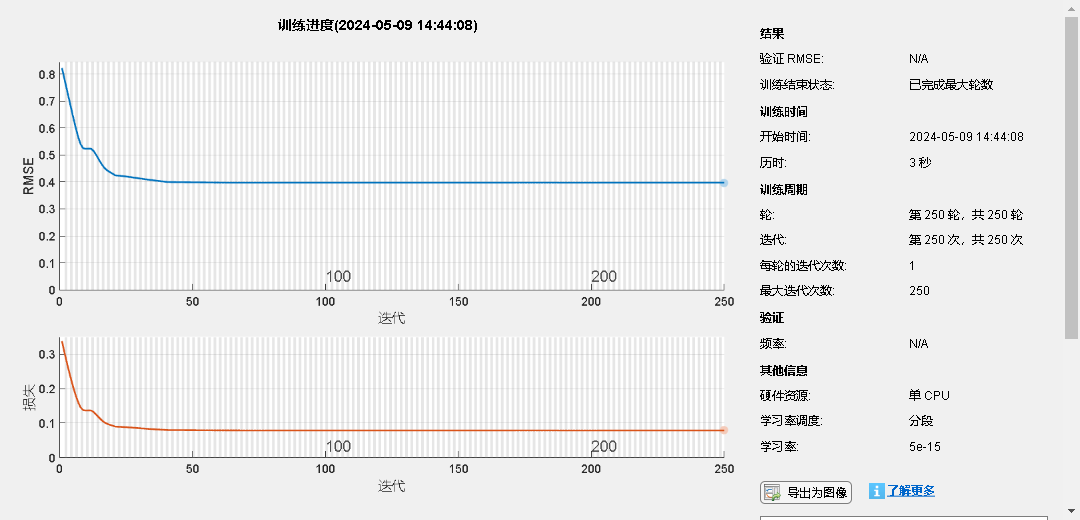

%dataSecond = [20.75, 18.89, 18.75, 20.15, 18.93, 18.81, 18.82, 15.81, 14.81, 13.1, 14.24, 16.21, 16.44, 19.02, 39.07, 63.72, 78.68, 84, 55.35, 50.63, 62.05, 73.16, 75.01, 71.46727273, 74.42867589, 74.39];
numTimeStepsTrainSecond = numel(dataSecond); 
dataTrainSecond = dataSecond(1 : numTimeStepsTrainSecond);

% 数据标准化，零均值和单位方差
musecond = mean(dataTrainSecond);
sigsecond = std(dataTrainSecond);
dataTrainStandardizedSecond = (dataTrainSecond - musecond) / sigsecond;

% 训练数据
XTrainSecond = dataTrainStandardizedSecond(1:end-1);
YTrainSecond = dataTrainStandardizedSecond(2:end);

% 创建 LSTM 网络
numFeaturesSecond= 1;
numResponsesSecond = 1;
numHiddenUnitsSecond = 20;

layersSecond = [sequenceInputLayer(numFeaturesSecond)
          lstmLayer(numHiddenUnitsSecond)
          fullyConnectedLayer(numResponsesSecond)
          regressionLayer];

% 设置网络参数
optionsSecond = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netSecond = trainNetwork(XTrainSecond, YTrainSecond, layersSecond, optionsSecond);

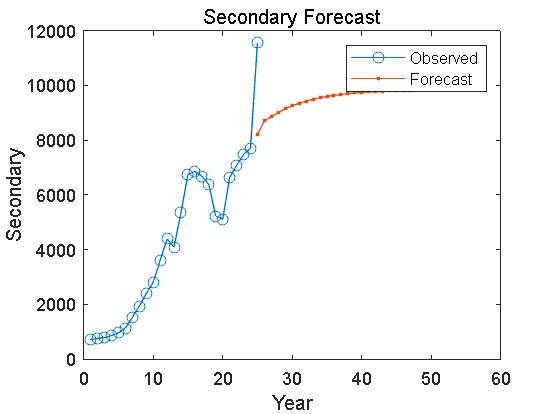


% 预测
netSecond = predictAndUpdateState(netSecond, XTrainSecond);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netSecond, YPredSecond] = predictAndUpdateState(netSecond, YTrainSecond(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictSecond = 28;
YPredSecond = [YPredSecond zeros(1, numYearsToPredictSecond - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictSecond
    [netSecond, YPredSecond(:, i)] = predictAndUpdateState(netSecond, YPredSecond(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredSecond = sigsecond * YPredSecond + musecond;
% 画图
figure;
plot(1:numel(dataSecond), dataSecond, '-o')
hold on
idx = numel(dataSecond) : (numel(dataSecond) + numYearsToPredictSecond - 1);
plot(idx, YPredSecond, '.-')
hold off 
xlabel("Year");
ylabel("Secondary");
title("Secondary Forecast");
legend("Observed", "Forecast");

disp(YPredSecond)

   1.0e+03 *

    8.2161    8.7058    8.8533    9.0152    9.1445    9.2548    9.3474    9.4257    9.4917    9.5474    9.5945    9.6344    9.6683    9.6971    9.7216    9.7425    9.7604    9.7757    9.7888    9.8001    9.8097    9.8181    9.8253    9.8315    9.8369    9.8416    9.8456    9.8491



## 煤炭等化石能源消耗量的LSTM模型

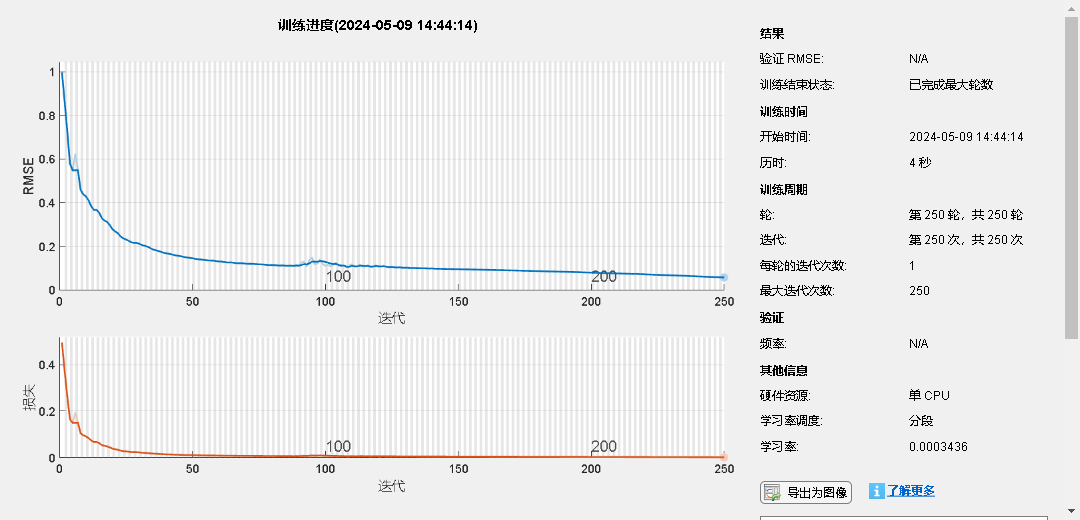

numTimeStepsTrainEnergy = numel(dataEnergy); 
dataTrainEnergy = dataEnergy(1 : numTimeStepsTrainEnergy);

% 数据标准化，零均值和单位方差
muEnergy = mean(dataTrainEnergy);
sigEnergy = std(dataTrainEnergy);
dataTrainStandardizedEnergy = (dataTrainEnergy - muEnergy) / sigEnergy;

% 训练数据
XTrainEnergy = dataTrainStandardizedEnergy(1:end-1);
YTrainEnergy = dataTrainStandardizedEnergy(2:end);

% 创建 LSTM 网络
numFeaturesEnergy= 1;
numResponsesEnergy = 1;
numHiddenUnitsEnergy = 100;

layersEnergy = [sequenceInputLayer(numFeaturesEnergy)
          lstmLayer(numHiddenUnitsEnergy)
          fullyConnectedLayer(numResponsesEnergy)
          regressionLayer];

% 设置网络参数
optionsEnergy = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.8, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同化石能源消耗背景下，改这个就行LearnRateDropFactor'/但怎么解释呢？
% 训练
netEnergy = trainNetwork(XTrainEnergy, YTrainEnergy, layersEnergy, optionsEnergy);

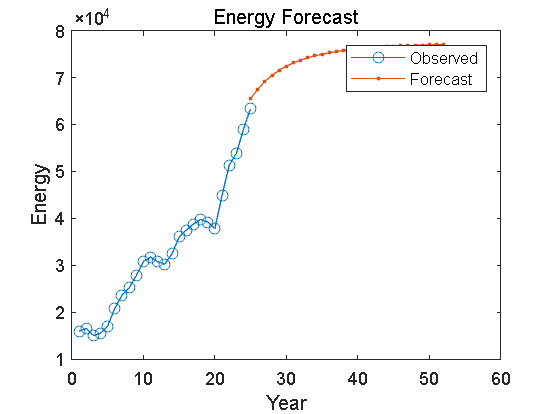


% 预测
netEnergy = predictAndUpdateState(netEnergy, XTrainEnergy);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netEnergy, YPredEnergy] = predictAndUpdateState(netEnergy, YTrainEnergy(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictEnergy = 28;
YPredEnergy = [YPredEnergy zeros(1, numYearsToPredictEnergy - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictEnergy
    [netEnergy, YPredEnergy(:, i)] = predictAndUpdateState(netEnergy, YPredEnergy(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredEnergy = sigEnergy * YPredEnergy + muEnergy;
% 画图
figure;
plot(1:numel(dataEnergy), dataEnergy, '-o')
hold on
idx = numel(dataEnergy) : (numel(dataEnergy) + numYearsToPredictEnergy - 1);
plot(idx, YPredEnergy, '.-')
hold off 
xlabel("Year");
ylabel("Energy");
title("Energy Forecast");
legend("Observed", "Forecast");

disp(YPredEnergy)

   1.0e+04 *

    6.5535    6.7516    6.9194    7.0507    7.1568    7.2431    7.3140    7.3728    7.4219    7.4632    7.4982    7.5280    7.5535    7.5754    7.5943    7.6106    7.6248    7.6372    7.6480    7.6575    7.6658    7.6731    7.6796    7.6854    7.6904    7.6950    7.6990    7.7026



## 天然气的LSTM模型

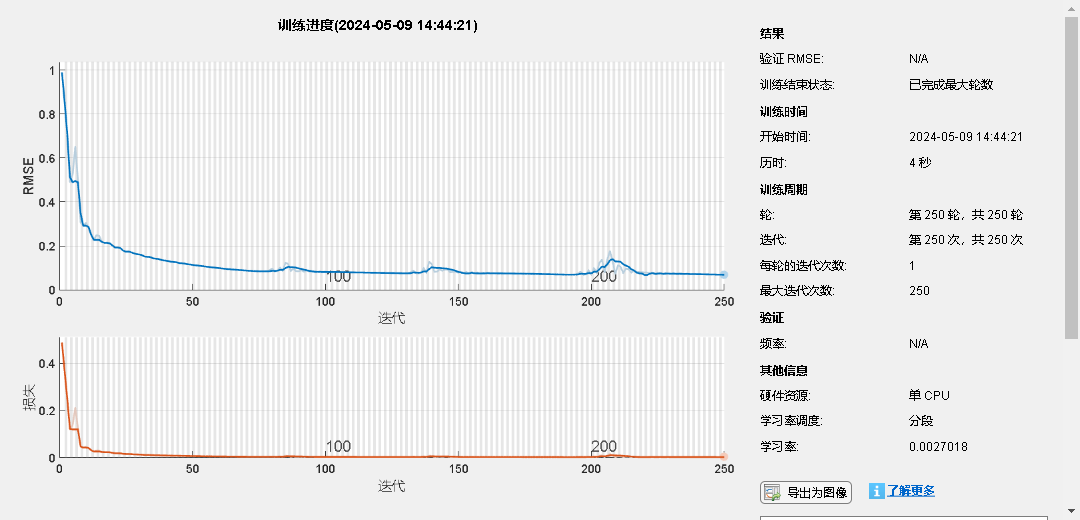

numTimeStepsTrainNaturalgas = numel(dataNaturalgas); 
dataTrainNaturalgas = dataNaturalgas(1 : numTimeStepsTrainNaturalgas);

% 数据标准化，零均值和单位方差
muNaturalgas = mean(dataTrainNaturalgas);
sigNaturalgas = std(dataTrainNaturalgas);
dataTrainStandardizedNaturalgas = (dataTrainNaturalgas - muNaturalgas) / sigNaturalgas;

% 训练数据
XTrainNaturalgas = dataTrainStandardizedNaturalgas(1:end-1);
YTrainNaturalgas = dataTrainStandardizedNaturalgas(2:end);

% 创建 LSTM 网络
numFeaturesNaturalgas= 1;
numResponsesNaturalgas = 1;
numHiddenUnitsNaturalgas = 100;

layersNaturalgas = [sequenceInputLayer(numFeaturesNaturalgas)
          lstmLayer(numHiddenUnitsNaturalgas)
          fullyConnectedLayer(numResponsesNaturalgas)
          regressionLayer];

% 设置网络参数
optionsNaturalgas = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.95, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Naturalgas背景下，改这个就行LearnRateDropFactor'
% 训练
netNaturalgas = trainNetwork(XTrainNaturalgas, YTrainNaturalgas, layersNaturalgas, optionsNaturalgas);

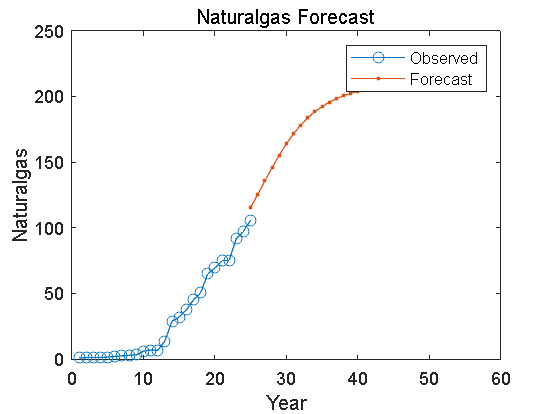


% 预测
netNaturalgas = predictAndUpdateState(netNaturalgas, XTrainNaturalgas);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netNaturalgas, YPredNaturalgas] = predictAndUpdateState(netNaturalgas, YTrainNaturalgas(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictNaturalgas = 28;
YPredNaturalgas = [YPredNaturalgas zeros(1, numYearsToPredictNaturalgas - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictNaturalgas
    [netNaturalgas, YPredNaturalgas(:, i)] = predictAndUpdateState(netNaturalgas, YPredNaturalgas(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredNaturalgas = sigNaturalgas * YPredNaturalgas + muNaturalgas;
% 画图
figure;
plot(1:numel(dataNaturalgas), dataNaturalgas, '-o')
hold on
idx = numel(dataNaturalgas) : (numel(dataNaturalgas) + numYearsToPredictNaturalgas - 1);
plot(idx, YPredNaturalgas, '.-')
hold off 
xlabel("Year");
ylabel("Naturalgas");
title("Naturalgas Forecast");
legend("Observed", "Forecast");

disp(YPredNaturalgas)

  115.4358  125.4867  135.6999  145.7105  155.1731  163.8122  171.4606  178.0648  183.6628  188.3503  192.2488  195.4815  198.1613  200.3850  202.2337  203.7739  205.0600  206.1366  207.0399  207.7999  208.4410  208.9835  209.4438  209.8358  210.1707  210.4577  210.7047  210.9180



## 科技发展LSTM模型

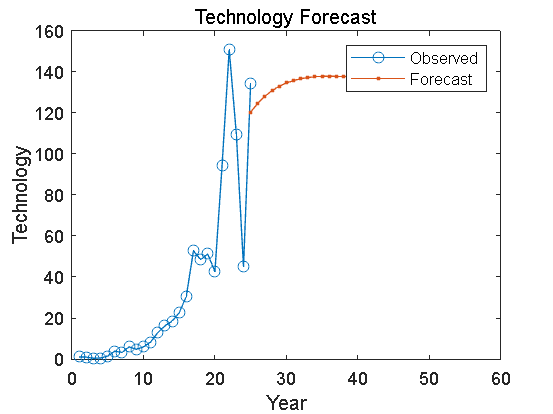

numTimeStepsTrainTechnology = numel(dataTechnology); 
dataTrainTechnology = dataTechnology(1 : numTimeStepsTrainTechnology);

% 数据标准化，零均值和单位方差
muTechnology = mean(dataTrainTechnology);
sigTechnology = std(dataTrainTechnology);
dataTrainStandardizedTechnology = (dataTrainTechnology - muTechnology) / sigTechnology;

% 训练数据
XTrainTechnology = dataTrainStandardizedTechnology(1:end-1);
YTrainTechnology = dataTrainStandardizedTechnology(2:end);

% 创建 LSTM 网络
numFeaturesTechnology= 1;
numResponsesTechnology = 1;
numHiddenUnitsTechnology = 100;

layersTechnology = [sequenceInputLayer(numFeaturesTechnology)
          lstmLayer(numHiddenUnitsTechnology)
          fullyConnectedLayer(numResponsesTechnology)
          regressionLayer];

% 设置网络参数
optionsTechnology = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Water背景下，'LearnRateDropFactor', 0.92大概会在2033碳达峰 ，0.95大概2030年...
% 训练
netTechnology = trainNetwork(XTrainTechnology, YTrainTechnology, layersTechnology, optionsTechnology);

% 预测
netTechnology = predictAndUpdateState(netTechnology, XTrainTechnology);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netTechnology, YPredTechnology] = predictAndUpdateState(netTechnology, YTrainTechnology(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictTechnology = 28;
YPredTechnology = [YPredTechnology zeros(1, numYearsToPredictTechnology - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictTechnology
    [netTechnology, YPredTechnology(:, i)] = predictAndUpdateState(netTechnology, YPredTechnology(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredTechnology = sigTechnology * YPredTechnology + muTechnology;
% 画图
figure;
plot(1:numel(dataTechnology), dataTechnology, '-o')
hold on
idx = numel(dataTechnology) : (numel(dataTechnology) + numYearsToPredictTechnology - 1);
plot(idx, YPredTechnology, '.-')
hold off 
xlabel("Year");
ylabel("Technology");
title("Technology Forecast");
legend("Observed", "Forecast");

disp(YPredTechnology)

  120.2935  124.6291  128.0564  130.7755  132.8855  134.4906  135.6832  136.5426  137.1349  137.5142  137.7247  137.8021  137.7752  137.6674  137.4973  137.2801  137.0281  136.7510  136.4570  136.1523  135.8423  135.5310  135.2217  134.9171  134.6193  134.3298  134.0498  133.7803



## 水力发电的百分占比LSTM模型

dataWaterpercent_2= dataTable.WaterPercent(1:25);
dataWaterpercent_1=dataWaterpercent_2*100;
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_1=(dataWaterpower_kilowatt / dataTotalpower_kilowatt)*100;
dataWaterpercent=dataWaterpercent_1.';
disp(dataWaterpercent);

   1.0e+03 *

    0.5760    0.6010    1.1390    1.3040    1.6730    1.8830    1.9290    2.1000    2.0320    2.3870    4.7320    2.3360    2.1660    3.6630    3.4630    4.0920    3.8870    3.2930    2.9260    3.7500    4.2220    4.3180    4.9070    4.6760    4.9917



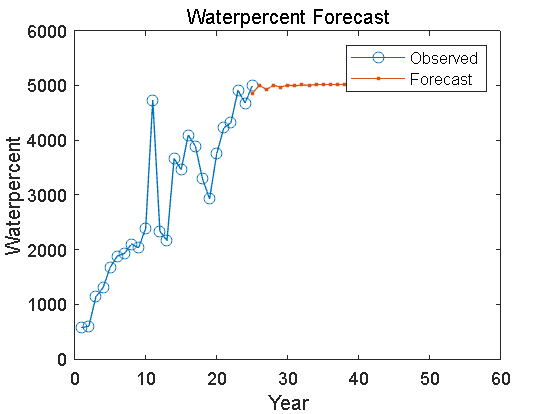


numTimeStepsTrainWaterpercent = numel(dataWaterpercent); % 使用所有的数据来训练
dataTrainWaterpercent = dataWaterpercent(1 : numTimeStepsTrainWaterpercent);

% 数据标准化，零均值和单位方差
muWaterpercent = mean(dataTrainWaterpercent);
sigWaterpercent = std(dataTrainWaterpercent);
dataTrainStandardizedWaterpercent = (dataTrainWaterpercent - muWaterpercent) / sigWaterpercent;

% 训练数据
XTrainWaterpercent = dataTrainStandardizedWaterpercent(1:end-1);
YTrainWaterpercent = dataTrainStandardizedWaterpercent(2:end);

% 创建 LSTM 网络
numFeaturesWaterpercent= 1;
numResponsesWaterpercent = 1;
numHiddenUnitsWaterpercent = 130;

layersWaterpercent = [sequenceInputLayer(numFeaturesWaterpercent)
          lstmLayer(numHiddenUnitsWaterpercent)
          fullyConnectedLayer(numResponsesWaterpercent)
          regressionLayer];

% 设置网络参数
optionsWaterpercent = trainingOptions('adam', ...
    'MaxEpochs', 550, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.95, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Water背景下，改这个就'LearnRateDropFactor', 0.92大概会在2033碳达峰 ，0.95大概2030年...
% 训练
netWaterpercent = trainNetwork(XTrainWaterpercent, YTrainWaterpercent, layersWaterpercent, optionsWaterpercent);

% 预测
netWaterpercent = predictAndUpdateState(netWaterpercent, XTrainWaterpercent);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netWaterpercent, YPredWaterpercent] = predictAndUpdateState(netWaterpercent, YTrainWaterpercent(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictWaterpercent = 28;
YPredWaterpercent = [YPredWaterpercent zeros(1, numYearsToPredictWaterpercent - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictWaterpercent
    [netWaterpercent, YPredWaterpercent(:, i)] = predictAndUpdateState(netWaterpercent, YPredWaterpercent(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredWaterpercent = sigWaterpercent * YPredWaterpercent + muWaterpercent;
% 画图
figure;
plot(1:numel(dataWaterpercent), dataWaterpercent, '-o')
hold on
idx = numel(dataWaterpercent) : (numel(dataWaterpercent) + numYearsToPredictWaterpercent - 1);
plot(idx, YPredWaterpercent, '.-')
hold off 
xlabel("Year");
ylabel("Waterpercent");
title("Waterpercent Forecast");
legend("Observed", "Forecast");

disp(YPredWaterpercent)

   1.0e+03 *

    4.8509    4.9999    4.9254    5.0022    4.9655    5.0056    4.9883    5.0096    5.0018    5.0132    5.0101    5.0164    5.0153    5.0189    5.0188    5.0209    5.0211    5.0224    5.0228    5.0236    5.0239    5.0245    5.0248    5.0252    5.0254    5.0257    5.0259    5.0261



## 原始STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Shanxi_data.xlsx'; 
dataTable = readtable(filename);

dataPopulation = dataTable.Population_wan(1:25) * 1e4;
dataGDP = dataTable.Per_capita_GDP_yuan(1:25); 
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25); % 技术市场交易量
dataEmission = dataTable.CarbonEmissions_mt(1:25); 

% 创建数据矩阵
dataMatrix = [dataPopulation, dataGDP, dataTechnology, dataEmission];

% 对数转换
dataLog = log(dataMatrix + 1); % 加1是为了避免对0取对数

% 将对数转换后的数据转换为dataTable
dataTableLog = array2table(dataLog, 'VariableNames', {'LogPopulation', 'LogGDP', 'LogTechnology', 'LogEmission'});

% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 变量名
variableNames = {'Population', 'GDP', 'Technology', 'Emission'};

% 显示相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                  Population      GDP      Technology    Emission
                  __________    _______    __________    ________

    Population           1      0.93613     0.88946      0.85351 
    GDP            0.93613            1     0.97294      0.94028 
    Technology     0.88946      0.97294           1      0.95664 
    Emission       0.85351      0.94028     0.95664            1 




% 绘制热力图
%figure;
%h = heatmap(variableNames, variableNames, correlationMatrix);
%h.Title = 'Pearson Correlation Matrix Heatmap';
%h.Colormap = bone; % 颜色映射选择
%h.ColorScaling = 'scaledcolumns'; % 颜色标准化

% 拟合模型
lm_formula = 'LogEmission ~ LogPopulation + LogGDP + LogTechnology';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogEmission ~ 1 + LogPopulation + LogGDP + LogTechnology

估计系数:
                     Estimate      SE        tStat       pValue 
                     ________    _______    ________    ________

    (Intercept)       42.969      84.606     0.50788     0.61683
    LogPopulation    -2.3595      5.0083    -0.47111     0.64242
    LogGDP           0.33315     0.41411      0.8045     0.43012
    LogTechnology    0.50298     0.18871      2.6654    0.014476


观测值数目: 25，误差自由度: 21
均方根误差: 0.306
R 方: 0.918，调整 R 方 0.906
F 统计量(常量模型): 78.1，p 值 = 1.48e-11


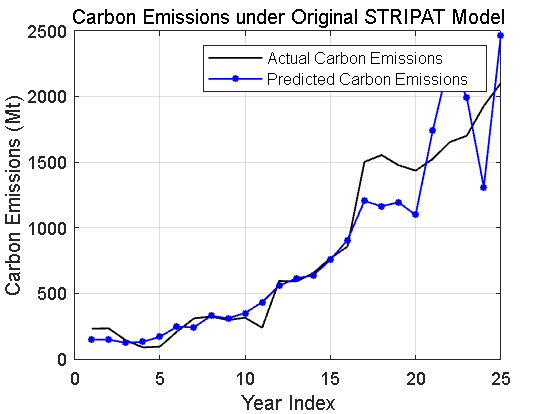


% 原始结果曲线图
figure;
plot(exp(dataTableLog.LogEmission), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Original STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 改良STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Shanxi_data.xlsx'; 
dataTable = readtable(filename);

% 数据提取与转换 重新提取一下 变原单位
dataGDP = dataTable.Per_capita_GDP_yuan(1:25);
dataPopulation = dataTable.Population_wan(1:25) * 1e4;
dataSecond = dataTable.Value_added_of_the_secondary_industry_billion(1:25) * 1e9;
dataCE = dataTable.CarbonEmissions_mt(1:25);
energyconsumption = (dataTable.Coal_consumption_10000_tons(1:25) + dataTable.Coke_consumption_10000_tons(1:25) + dataTable.Fuel_oil_consumption_10000_tons(1:25)) * 1e4;
dataNaturalgas = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25) * 1e9;
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25) * 1e8;
hydroPower = dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
totalPower = dataTable.Total_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
dataWaterPercent = (hydroPower ./ totalPower) * 100;

% 数据标准化处理
dataMatrix = [dataCE, dataGDP, dataPopulation, dataSecond, energyconsumption, dataNaturalgas, dataTechnology, dataWaterPercent];

% 对数转换，直接处理
dataLog = log(dataMatrix+1);
% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 定义变量名称
variableNames = {'CarbonEmissions', 'GDP', 'Population', 'SecondaryIndustry', 'EnergyConsumption', 'NaturalGas', 'TechnologyTransactions', 'HydroPowerPercentage'};

% 输出相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                              CarbonEmissions      GDP       Population    SecondaryIndustry    EnergyConsumption    NaturalGas    TechnologyTransactions    HydroPowerPercentage
                              _______________    ________    __________    _________________    _________________    __________    ______________________    ____________________

    CarbonEmissions                     1         0.94028      0.85351           0.9104              0.92725           0.95248             0.94926                 -0.58268      
    GDP                           0.94028               1      0.93613          0.98981              0.97749           0.98476              0.9721                 -0.37789      
    Population                    0.85351         0.93613            1          0.95083              0.87015           0.93337             0.90334                 -0.26711      
    SecondaryIndustry              0.9104         0.98981      0.95083                1               0.9638 

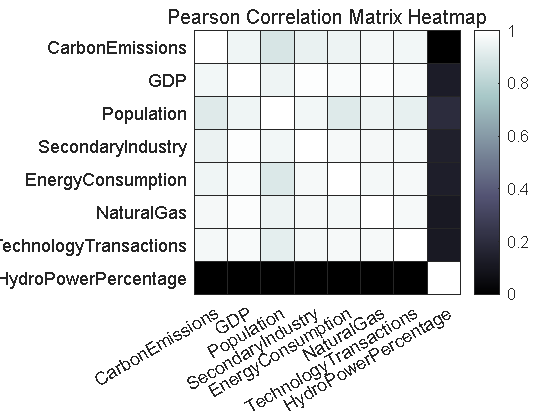


% 热力图
figure; % bone配色行 好看
%mycolor = [0.474509803921569,0.650980392156863,0.807843137254902;...
% 0.682352941176471,0.823529411764706,0.898039215686275;...
 %0.941176470588235,0.972549019607843,0.862745098039216;...
 %0.992156862745098,0.968627450980392,0.705882352941177;...
 %1,0.901960784313726,0.603921568627451];
h = heatmap(variableNames, variableNames, correlationMatrix);
h.Title = 'Pearson Correlation Matrix Heatmap';
h.Colormap = bone; 
h.ColorScaling = 'scaledcolumns'; 

%colormap(gca,mycolor);


% 创建数据表格
variableNames = {'LogCE','LogGDP', 'LogPopulation', 'LogSecond',  'LogEnergyConsumption', 'LogNaturalGas', 'LogTechnology', 'LogWaterPercent'};
dataTableLog = array2table(dataLog, 'VariableNames', variableNames);

% 拟合模型
lm_formula = 'LogCE ~ LogPopulation + LogGDP + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogCE ~ 1 + LogGDP + LogPopulation + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent

估计系数:
                            Estimate       SE         tStat        pValue  
                            _________    _______    _________    __________

    (Intercept)               -36.884     125.95     -0.29283        0.7732
    LogGDP                  -0.021228     1.2295    -0.017266       0.98643
    LogPopulation              1.8119     7.9605      0.22761       0.82266
    LogSecond                -0.29907    0.87654     -0.34119       0.73714
    LogEnergyConsumption       0.5772    0.68842      0.83845       0.41341
    LogNaturalGas             0.28326    0.32731      0.86541       0.39886
    LogTechnology             0.19969    0.11379       1.7549      0.097281
    LogWaterPercent            -1.532    0.35302      -4.3397    0.00044528


观测值数目: 25，误差自由度: 17
均方根误差: 0.207
R 方: 0.97，调整 R 方 0.957
F 统计量(常量模型): 77.3，p 值 = 1.22e-11


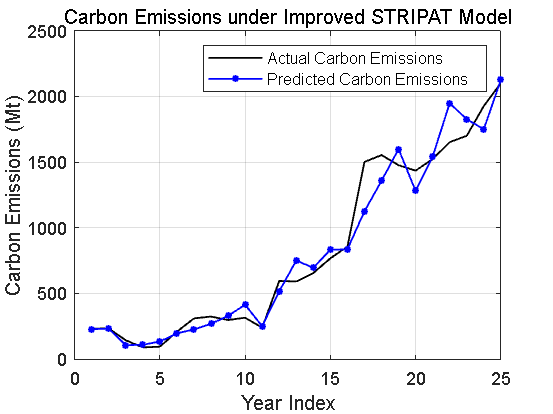


lmCoefficients = model.Coefficients.Estimate; % 存储系数
% 绘制结果曲线图
figure;
plot(exp(dataTableLog.LogCE), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Improved STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 将预测得到的各个YPred的LSTM值带入到改良STRIPAT模型

YPredLogGDP = log(YPredGDP).';  
YPredLogPopulation = log(YPredPopulation).';
YPredLogSecond = log(YPredSecond).';
YPredLogEnergy = log(YPredEnergy).';
YPredLogNaturalGas = log(YPredNaturalgas).';
YPredLogTechnology = log(YPredTechnology).';
YPredLogWaterPercent = log(YPredWaterpercent).';
dataCE = dataTable.CarbonEmissions_mt(1:25); % 真实碳排放数据
Years = dataTable.Year(1:25); 

PredictedLogCE = lmCoefficients(1) + lmCoefficients(3) * YPredLogGDP + lmCoefficients(2) * YPredLogPopulation + ...
                 lmCoefficients(4) * YPredLogSecond + lmCoefficients(5) * YPredLogEnergy + ...
                 lmCoefficients(6) * YPredLogNaturalGas + lmCoefficients(7) * YPredLogTechnology + ...
                 lmCoefficients(8) * YPredLogWaterPercent;

PredictedCE_1 = exp(PredictedLogCE);
PredictedCE = (PredictedCE_1)*1e14+1500;
% 输出预测结果
disp('Predicted CarbonEmissions for future years:');

Predicted CarbonEmissions for future years:


disp(PredictedCE);

   1.0e+03 *

    2.0111
    2.0431
    2.1127
    2.1474
    2.1985
    2.2270
    2.2626
    2.2840
    2.3079
    2.3232
    2.3390
    2.3497
    2.3600
    2.3674
    2.3742
    2.3791
    2.3837
    2.3872
    2.3904
    2.3929
    2.3951
    2.3968
    2.3983
    2.3995
    2.4005
    2.4014
    2.4021
    2.4026



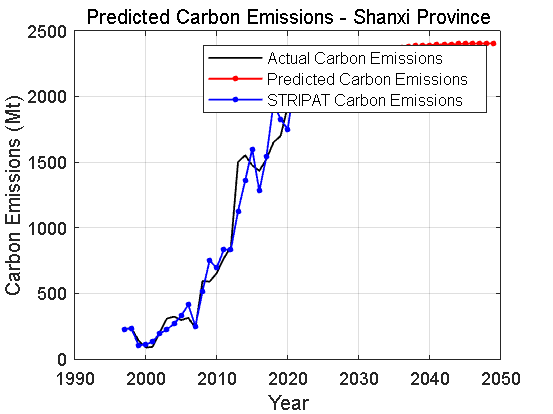

% 实际与预测的碳排放量对比
figure;
plot(Years, dataCE, 'k', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Actual Carbon Emissions');
hold on;
plot(Years(1) + (25:52), PredictedCE, 'r*-', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Predicted Carbon Emissions');
%STRIPATPred=exp(PredictedCE);
plot(Years(1)+ (0:24), exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'STRIPAT Carbon Emissions');
title('Predicted Carbon Emissions - Shanxi Province');
xlabel('Year');
ylabel('Carbon Emissions (Mt)');
legend show;
grid on;
hold off;